# Sample 6-2

## 標本化

単変量ダウンサンプリング

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Sampling

Univariate downsampling

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 間引き率の設定

(Setting the downsampling factor)

- $M$: 間引き率 (downsampling factor)

% Downsampling factor
dFactor = 2;

### 入力数列の設定

(Setting the input sequence)

- $\{u[n]\}_n$: 入力数列 (input sequence)

% Create a sequence from sound data
startIndex = 256;
nInputSamples = 32;
load gong;
inputSeq = y(startIndex:startIndex+nInputSamples-1);
load chirp;
inputSeq = inputSeq + y(startIndex:startIndex+nInputSamples-1);

### 出力数列の計算

(Computation of the output sequence)

- $\{v[n]\}_n$: 出力数列 (output sequence)

        
$$v[m] = u[Mm],\ m\in\mathbb{Z}$$


% Downsampling
outputSeq = downsample(inputSeq,dFactor);
nOutputSamples = length(outputSeq);

###  入出力数列の表示

(Display of the input and output sequences)

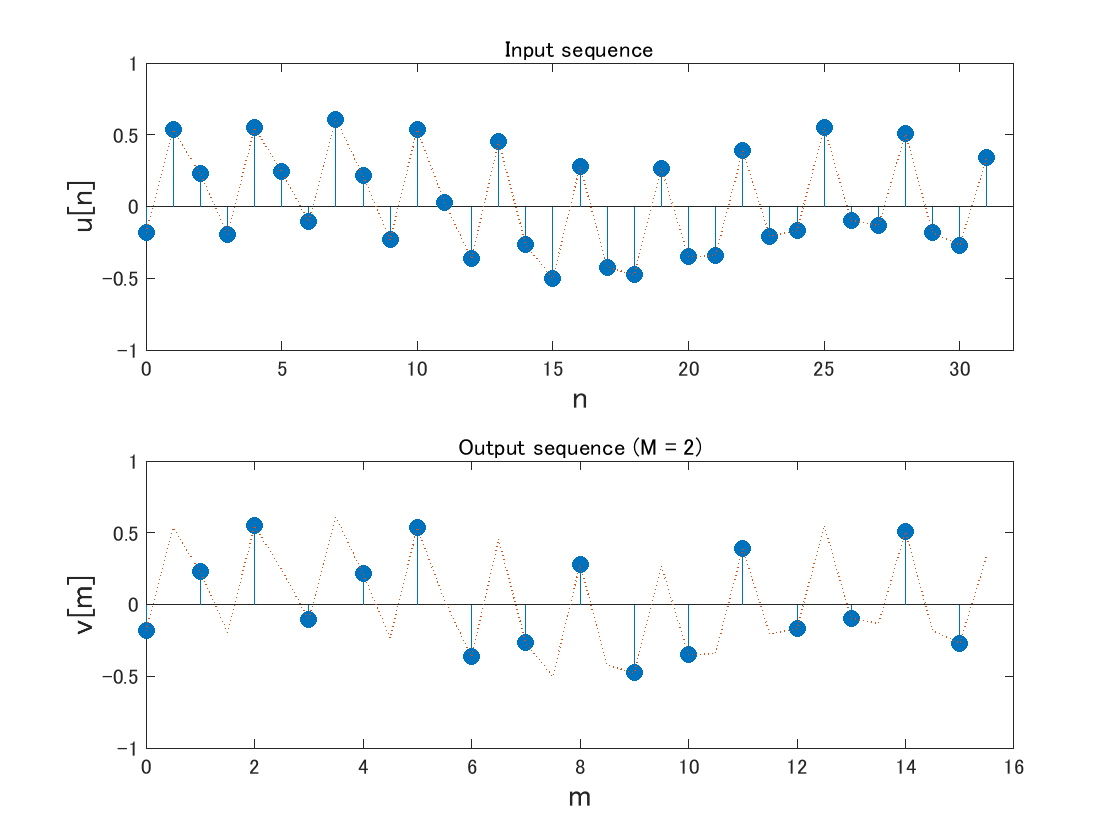

% Plot the input and output sequences
figure(1)
% Input sequence
subplot(2,1,1)
stem(0:nInputSamples-1,inputSeq,'filled')
hold on
plot(0:nInputSamples-1,inputSeq,':')
axis([0 nInputSamples -1 1])
title('Input sequence','FontSize',12)
xlabel('n','FontSize',12)
ylabel('u[n]','FontSize',12)
hold off

% Output sequence
subplot(2,1,2)
stem(0:nOutputSamples-1,outputSeq,'filled')
hold on
plot(0:1/dFactor:(nInputSamples-1)/dFactor,inputSeq,':')
axis([0 nInputSamples/dFactor -1 1])
title(sprintf('Output sequence (M = %d)',dFactor),'FontSize',12)
xlabel('m','FontSize',12)
ylabel('v[m]','FontSize',12)
hold off

###  入力数列の設定

(Setting the input sequence)

% Creation of a modulated Gaussian
w = 0; % Modulation frequency
nInputSamples = 128; 
inputSeq = gausswin(nInputSamples);
inputSeq = inputSeq/sum(inputSeq);
inputSeq = inputSeq.*cos((0:(nInputSamples-1)).'*w);

###  出力数列の計算

(Computation of the output sequence)

        
$$V(e^{\j\omega})=\frac{1}{M}\sum_{k=0}^{M-1}U\left(e^{\frac{\j(\omega-2\pi k)}{M}}\right)$$
 

% Downsampling
outputSeq = downsample(inputSeq,dFactor);
nOutputSamples = length(outputSeq);

### 入出力スペクトルの表示

(Display of the input and output spectrum)

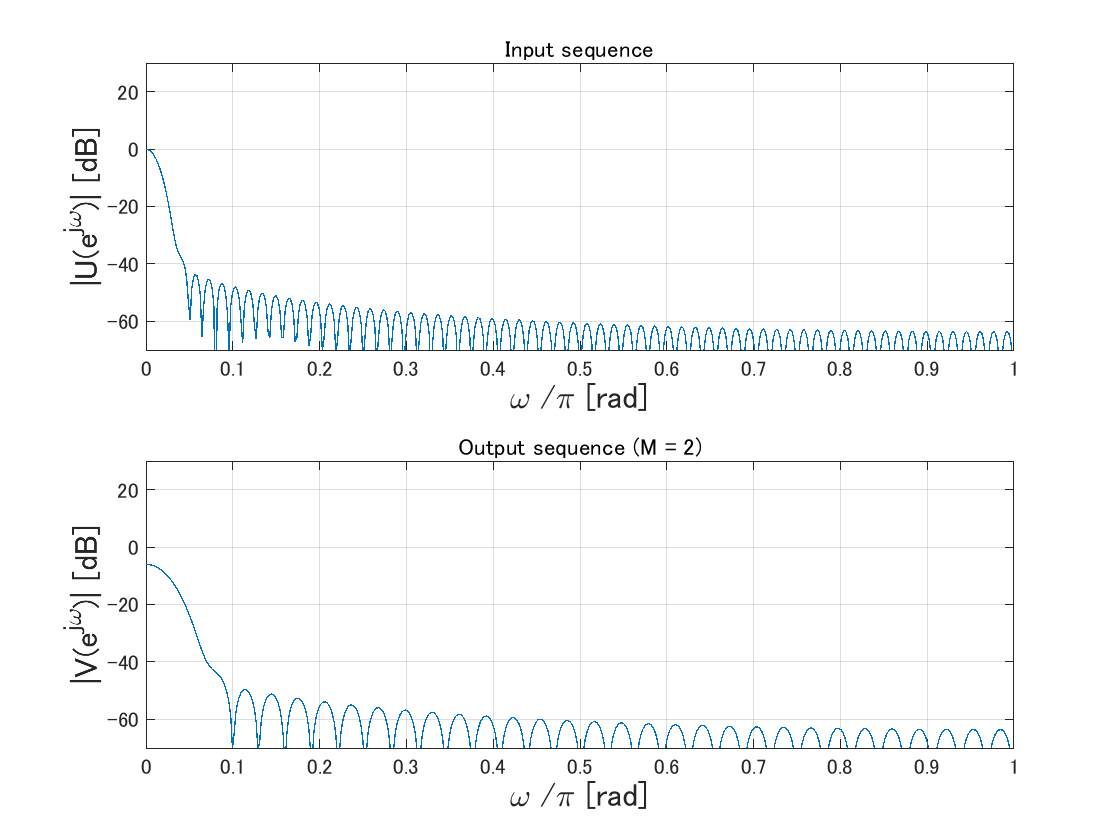

% Display spectra
figure(2)
% Input spectrum
subplot(2,1,1)
[H,W] = freqz(inputSeq);
plot(W/pi,20*log10(abs(H)))
title('Input sequence','FontSize',12)
xlabel('\omega /\pi [rad]','FontSize',12)
ylabel('|U(e^{j\omega})| [dB]','FontSize',12)
axis([ 0 1 -70 30 ])
grid on

% Output spectrum
subplot(2,1,2)
[H,W] = freqz(outputSeq);
plot(W/pi,20*log10(abs(H)))
title(sprintf('Output sequence (M = %d)',dFactor),'FontSize',12)
xlabel('\omega /\pi [rad]','FontSize',12)
ylabel('|V(e^{j\omega})| [dB]','FontSize',12)
axis([ 0 1 -70 30 ])
grid on

© Copyright, Shogo MURAMATSU, All rights reserved.